% dynamics
%xdot = Ax + Bu
A = [-10, 0, -10, 0;
    0, -0.7, 9, 0;
    0, -1, -0.7, 0;
    1, 0, 0, 0]

A =   -10.0000         0  -10.0000         0
         0   -0.7000    9.0000         0
         0   -1.0000   -0.7000         0
    1.0000         0         0         0


B = [20, 2.8;
    0, -3.13;
    0, 0;
    0, 0]

B =    20.0000    2.8000
         0   -3.1300
         0         0
         0         0



% unsafe control
Q = 10 * eye(4);
Q(1,1) = 0;
Q(2,2) = 0;
R = 5 * eye(2);

K = lqr(A,B,Q,R);

% simulate
tspan = [0 10]

tspan =      0    10


x0 = [5; 5; pi/9; pi/9]; % x, y, z, zd, yd, zd
[T,X] = ode45(@(t,x) unsafe_sol(t, x, A, B, K), tspan, x0);

plot(T,X)

%hold on
plot(X(:,3), X(:,4))

%axis equal

% linear embedded system
h0 = [0.5 + 0;
    0.5 - 0];
h02 = h0' * h0

h02 = 0.5000

hx0 = [0, 0, 1, 0;
    0, 0, 0, -1];
gamma = 1;

Az1 = -1/(h02) * hx0 * A - gamma * 1/(h02) * hx0

Az1 =          0    2.0000   -0.6000         0
    2.0000         0         0    2.0000


Az2 = -gamma*eye(2);
Bz = -1/(h02) * hx0 * B

Bz =      0     0
     0     0



Abar = [A zeros(4,2); Az1 Az2];
Bbar = [B;Bz];
Qbas = 1 * eye(2);
Qbar = [Q zeros(4,2); zeros(2,4) Qbas];

K_safe = lqr(Abar, Bbar, Qbar, R);

%z0 = [1 ./ (1 - x0(1)), 1./(1 - x0(2)), 1./(1 - x0(3))]' - 1./h0;
z0 = 1 ./ (0.5 + x0(3)) + 1./(0.5 - x0(4)) - 1./h0;
xbar0 = [x0;z0];

[T_safe,X_safe] = ode45(@(t,x) safe_sol(t, x, A, B, K_safe, gamma, h0), tspan, xbar0);
plot(T_safe,X_safe)

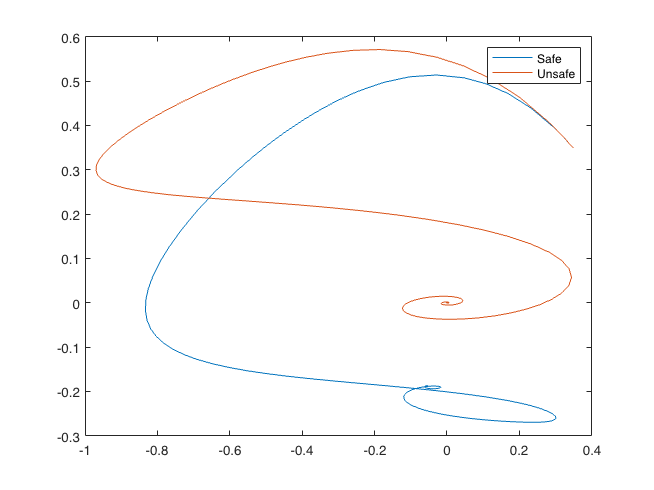

%hold on
plot(X_safe(:,3), X_safe(:,4))
hold on
plot(X(:,3), X(:,4))
legend('Safe', 'Unsafe')

min(X_safe(:,3))

ans = -0.8334

max(X_safe(:,4))

ans = 0.5139

## ode funcs

function dx = unsafe_sol(t, x, A, B, K)
u = -K * x;
dx = A*x + B*u;
end

function dx = safe_sol(t, x, A, B, K, gamma, h0)
u = -K * x;
dx = zeros(6,1);

dx(1:4) = A*x(1:4) + B*u;
h = [0.5 + x(3);
    0.5 - x(4)];
h2 = h0' * h0;
hx = [0, 0, 1, 0;
    0, 0, 0, -1];
zdot = -1/(h2) * hx * dx(1:4) - gamma * (x(5:6)' + 1/h0 - 1/h)';
dx(5:6) = zdot;
end

